# **demo12_gmsh of Im2mesh package**

Use polyshape to define geometry and generate mesh via Gmsh

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com   [Project website](https://github.com/mjx888/im2mesh)   [List of demo](https://mjx888.github.io/im2mesh_demo_html/demo_list.html)

## Note

Gmsh can be downloaded from [https://gmsh.info/bin/](https://gmsh.info/bin/) or [https://gmsh.info](https://gmsh.info)

If you plan to generate quadrilateral mesh, please download gmsh-4.13 or gmsh-4.14. I encountered a bug when using gmsh-4.15 to generate quadrilateral mesh.

## Initialize

**Before starting, we need to download Gmsh and un-zip.**

Please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 300; height = 300;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

We add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Single-part geometry

### A polyshape

Let's create a polyshape (for a single-part geometry). 

Suppose we want a square with a hole.

% square
vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);

Create a circle.

% circle
t = 0.05:0.05:2*pi;
x1 = 5 + 1.5*cos(t);
y1 = 5 + 1.5*sin(t);
psCircle = polyshape(x1,y1);

Plot them together.

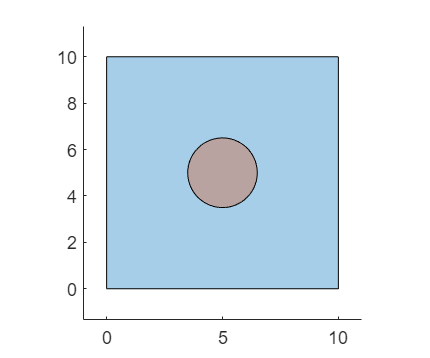

plot( [psSq; psCircle] ); 
axis equal

Perform boolean operation to create a square with a hole.

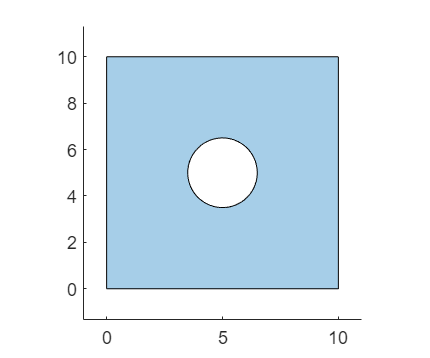

psSqHole = subtract(psSq, psCircle);

plot(psSqHole); 
axis equal

### Polygonal boundary

We use function polyshape2bound to convert a cell array of polyshape to a cell array of polygonal boundary. 

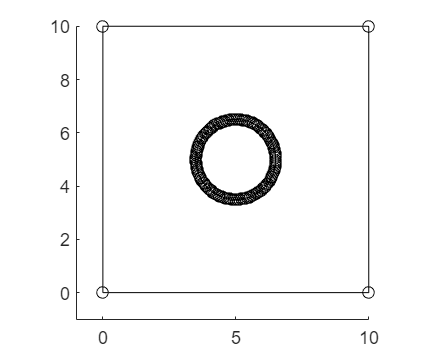

psCell = {psSqHole}; % psCell is a cell array of polyshape

bounds = polyshape2bound(psCell);

% plot boundaries and show all vertices
plotBounds(bounds,false,'ko-')

### **Simplify boundaries**

We want to reduce the number of vertices on the circle.

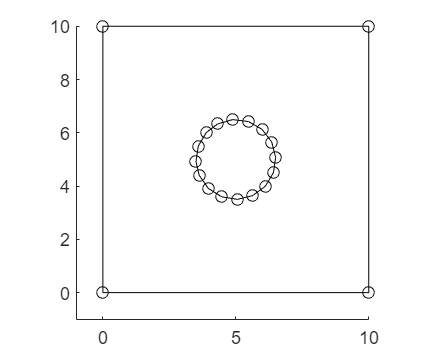

boundsCtrlP = getCtrlPnts( bounds );

% simplify polyline using Douglas-Peucker algorithm
tolerance = 0.05;
boundsReduced = simplifyBounds( boundsCtrlP, tolerance );

% show all vertices
plotBounds( boundsReduced, false, 'ko-' );    

### Generate mesh via Gmsh

To use Gmsh as mesh generator, we need to download Gmsh ([https://gmsh.info/bin/](https://gmsh.info/bin/) or [https://gmsh.info](https://gmsh.info)) and un-zip.

We need to know the location of gmesh.exe

% for example
path_to_gmsh = 'C:\Users\Jason\Downloads\gmsh-4.13.1-Windows64\gmsh.exe';

We can use Gmsh to generate triangular or quadrilateral mesh. Please refer to demo11 to learn about the meaning of the following functions.

Let's generate quasi-structured quadrilateral mesh. 

% setup parameters
opt = [];   % reset
opt.sizeMin = 0.1;
opt.sizeMax = 1.5;
opt.algthm = 11;
opt.recombAll = 0;
opt.recombAlgthm = 3;
opt.eleOrder = 1;

path_to_geo = 'gmshTemp.geo';

bounds2geo( boundsReduced, path_to_geo, opt );

bounds2geo Done! Check the geo file!


Send geo file to Gmsh.

path_to_m = 'gmshTemp.m';
verbosity = 3;
str=sprintf('"%s" "%s" -o "%s" -v %i -save', ... 
			path_to_gmsh, path_to_geo, path_to_m, verbosity );
system(str);


% run m file
run(path_to_m)
% struct variable 'msh' in the workspace of MATLAB
msh

msh = struct with fields:
    nbNod: 410
      POS: [410×3 double]
      MAX: [10 10 0]
      MIN: [0 0 0]
    QUADS: [358×5 double]


Before ploting the mesh, we need to do some processing to the mesh data. 

[vert,ele] = extractMsh( msh );

Plot mesh.

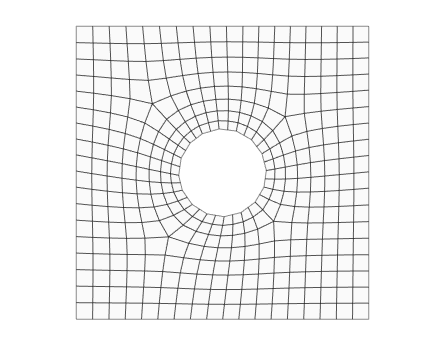

plotMeshes( vert, ele )

Awesome! Please refer to demo11 for how to evaluate mesh quality.

## Multi-part geometry

### Multiple polyshapes

Let's create multiple polyshapes for multi-part geometry.

clearvars

Start with a square.

vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);

Create three rods - A B C, and combine them using function union.

psRodBase = scale( psSq, [1, 0.05]);

psRodA = rotate( psRodBase, 155 );
psRodA = translate( psRodA, [6 8] );
psRodB = translate( psRodBase, [1 9] );
psRodC = translate( psRodBase, [-1 5] );

psRodABC = union([ psRodA; psRodB; psRodC ]);

Create a circle.

t = 0.05:0.03:2*pi;
x1 = 8 + 1.5*cos(t);
y1 = 9.5 + 1.5*sin(t);
psCircle = polyshape(x1,y1);

Plot them together.

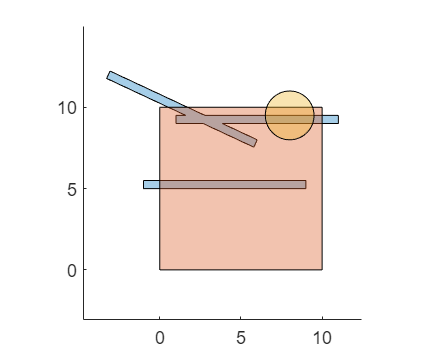

plot( [psRodABC; psSq; psCircle] ); 
axis equal

We saw that they are overlapped.

### Boolean operations

We use boolean operations to remove overlapped regions.

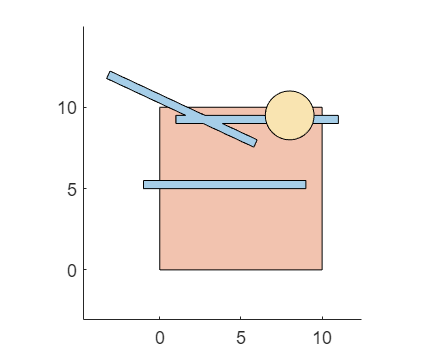

psBlock = subtract( psSq, psRodABC );
psBlock = subtract( psBlock, psCircle );

psRodABC = subtract( psRodABC, psCircle );

plot( [psRodABC; psBlock; psCircle] ); 
axis equal

### Cell array of polyshape

We put them into a cell array - psCell. Each element in psCell represent different parts. It's like labelling.

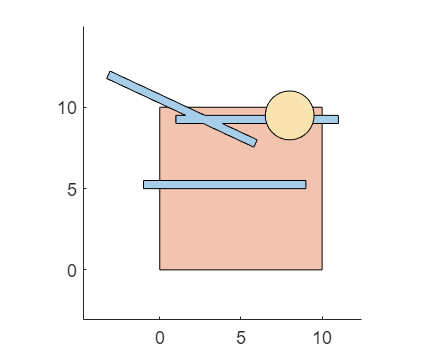

psCell = { psRodABC; psBlock; psCircle };

% plot psCell
figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

### Add intersect points

Polyshape objects are not able to find intersect points automatically. Therefore, we convert the cell array of polyshape 'psCell' to a cell array of polygonal boundaries 'bounds', and use function addIntersectPnts to add intersect points to 'bounds'. 

Note that if we don't add intersect points, mesh generation may fail.

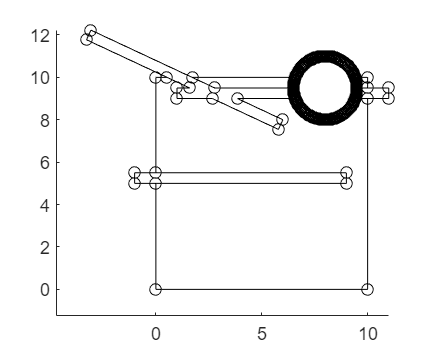

bounds = polyshape2bound(psCell);

tol_intersect = 1e-6;   % distance tolerance for intersect
bounds = addIntersectPnts( bounds, tol_intersect );

% plot boundaries and show all vertices
plotBounds(bounds,false,'ko-')

We saw that there are a lot of vertices on the circle.

### Simplify boundaries

We want to reduce the number of vertices on the circle.

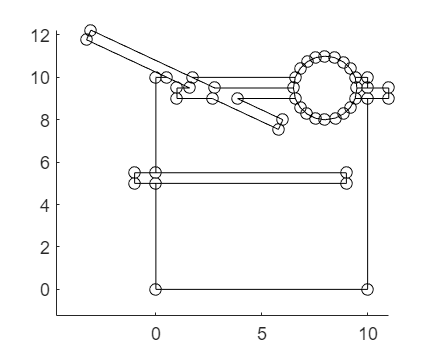

boundsCtrlP = getCtrlPnts( bounds );

% simplify polyline using Douglas-Peucker algorithm
tolerance = 0.025;
boundsReduced = simplifyBounds( boundsCtrlP, tolerance );

% show all vertices
plotBounds(boundsReduced,false,'ko-')

Awesome! We saw that the number of vertices on the circle reduced a lot.

Note that you need to adjust the value of tolerance to achieve your desired reduction.

### Generate mesh via Gmsh

We need to know the location of gmesh.exe

% for example
path_to_gmsh = 'C:\Users\Jason\Downloads\gmsh-4.13.1-Windows64\gmsh.exe';

We can use Gmsh to generate triangular or quadrilateral mesh. Please refer to demo11 to learn about the meaning of the following functions.

Let's generate unstructured quadrilateral mesh.

% setup parameters
opt = [];   % reset
opt.sizeMin = 0.05;
opt.sizeMax = 0.7;
opt.algthm = 8;
opt.recombAll = 1;
opt.recombAlgthm = 3;
opt.eleOrder = 1;

path_to_geo = 'gmshTemp.geo';

bounds2geo( boundsReduced, path_to_geo, opt );

bounds2geo Done! Check the geo file!


Send geo file to Gmsh.

path_to_m = 'gmshTemp.m';
verbosity = 3;
str=sprintf('"%s" "%s" -o "%s" -v %i -save', ... 
			path_to_gmsh, path_to_geo, path_to_m, verbosity );
system(str);


% run m file
run(path_to_m)
% struct variable 'msh' in the workspace of MATLAB
msh

msh = struct with fields:
    nbNod: 643
      POS: [643×3 double]
      MAX: [11 12.2262 0]
      MIN: [-3.2744 0 0]
    QUADS: [590×5 double]


Before ploting the mesh, we need to do some processing to the mesh data. 

[vert,ele,tnum] = extractMsh( msh );

 180 negative area elements are fixed.


Plot mesh.

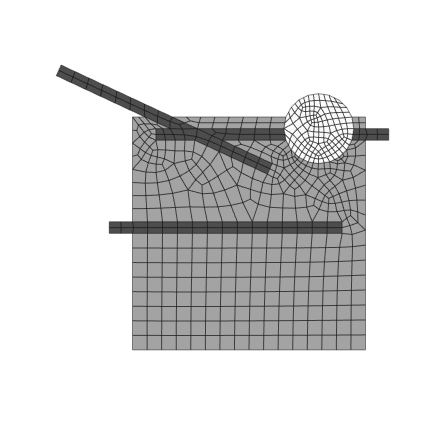

plotMeshes( vert, ele, tnum )

Awesome! Please refer to demo11 for how to evaluate mesh quality.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo